# LAB2 MATLAB Programming

涂峻绫(12213010) and 欧阳安男(12211831)

## Introduction

MATLAB is a powerful tool to handle on the problem of signal and system.

After completing this lab, we are able to,

- Use "conv" to convolve x and y to get the convolution result.

- Use "fliter" to remove the echos which are caused by time delay.

- Use "lsim" to simulate the output of continuous-time, causal LTI  systems described by linear constant-coefficient differential equations of the form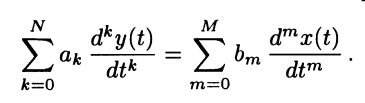

- Prove several propertites of convolution operation.

- Compare the difference of the infinite signal and the finite signal.

## Results and Analysis

### 2.4

#### (a)

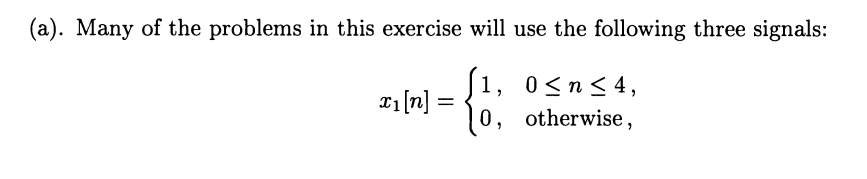    

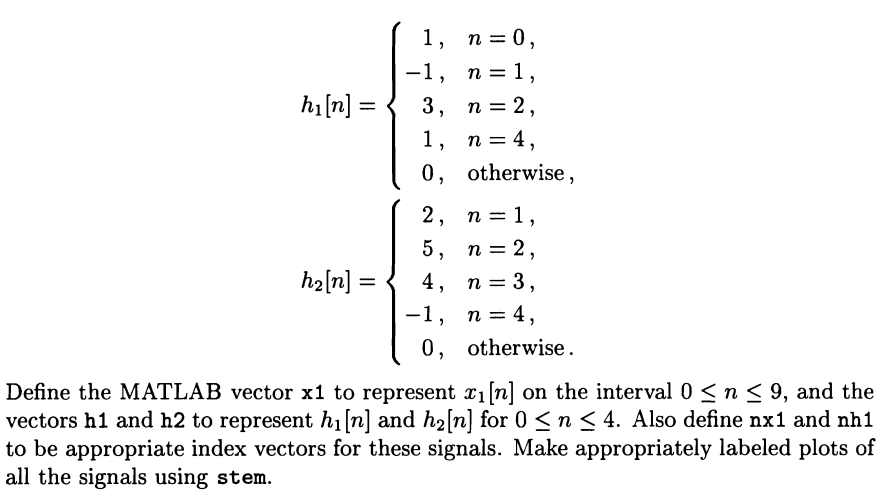

Initiate the three signals $x_1[n]$, $h_1[n]$, $h_2[n]$.

clear;clc;
x1 = [1 1 1 1 1 zeros(1,5)];
nx1 = 0:9;
h1 = [1 -1 3 0 4];
h2 = [0 0 1 0 3];
nh1 = 0:4;

Then stem the three signals.

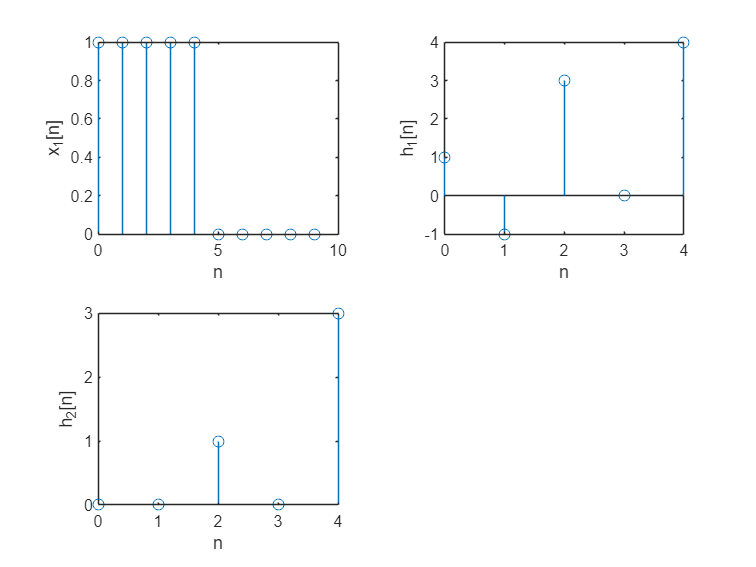

figure;
tiledlayout(2,2);
nexttile;stem(nx1,x1);
ylabel('x_1[n]');xlabel('n');
nexttile;stem(nh1,h1);
ylabel('h_1[n]');xlabel('n');
nexttile;stem(nh1,h2);
ylabel('h_2[n]');xlabel('n');

#### (b)

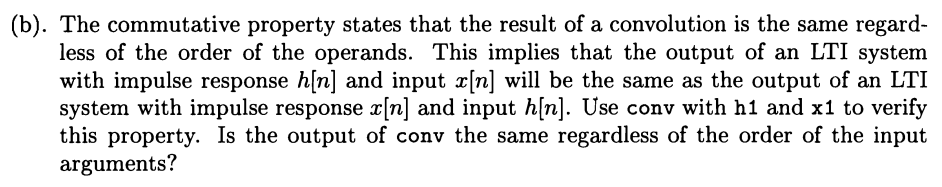

Introduce the three signals $x_1[n]$, $h_1[n]$, $h_2[n]$.

x1 = [1 1 1 1 1 zeros(1,5)];
nx1 = 0:9;
h1 = [1 -1 3 0 4];
h2 = [0 0 1 0 3];
nh1 = 0:4;

Let $h_1[n]$ be the impulse response and $x_1[n]$ be the input signal, then $y_1[n] = h_1[n] *x_1[n]$.

Then Let $x_1[n]$ be the impulse response and $h_1[n]$ be the input signal, then $y_2[n] = x_1[n] *h_1[n]$.

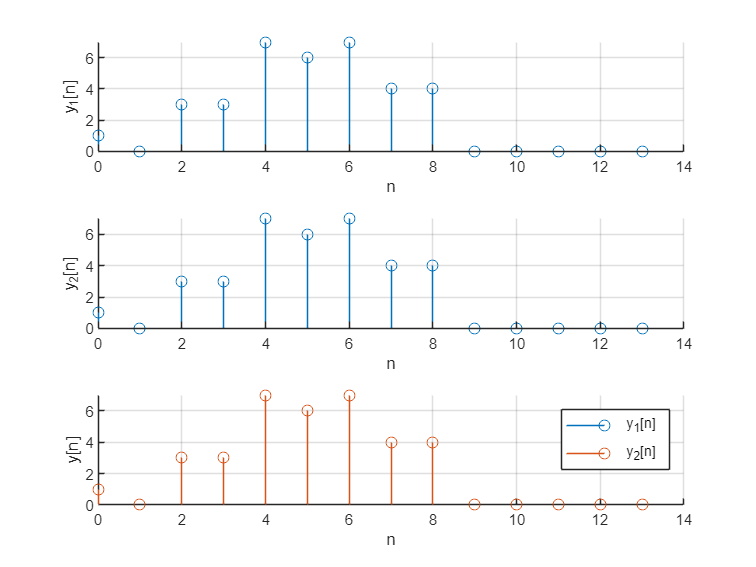

y1 = conv(h1, x1);
figure;
ny = (nx1(1) + nh1(1)):(nx1(end) + nh1(end));
tiledlayout(3,1);
nexttile;stem(ny,y1);
ylabel('y_1[n]');xlabel('n');grid on;box off;
y2 = conv(x1, h1);
nexttile;stem(ny,y2);
ylabel('y_2[n]');xlabel('n');grid on;box off;
nexttile;hold on;
stem(ny,y1);stem(ny,y2);
grid on;
xlabel('n');
ylabel('y[n]');
legend('y_1[n]', 'y_2[n]');

And now, we can use isequal() to compare the $y_1[n]$ and $y_2[n]$.

isequal(y1,y2)

ans = logical
   1


Since they are the same, the output of conv regardless of the order of the input arguments is the same.

#### **(c)**

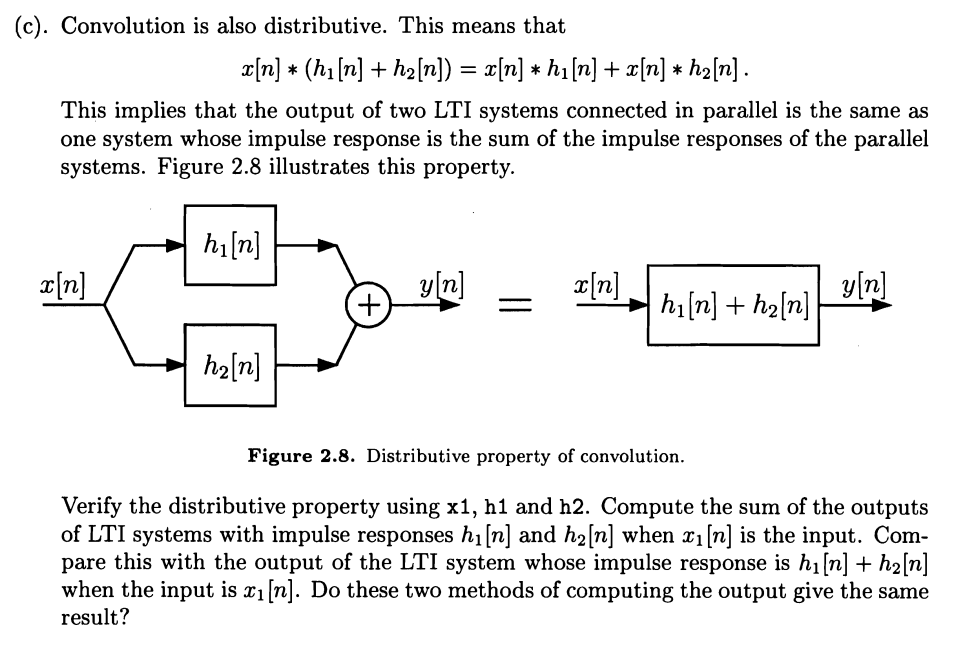    

Assume $y_1[n]=x[n]*h_1[n]+x[n]*h_2[n]$ and $y_2[n]=x[n]*(h_1[n]+h_2[n])$.

y1 = conv(x1,h1)+conv(x1,h2);
y2 = conv(x1,h1+h2);
ny = nx1(1)+nh1(1):nx1(end)+nh1(end);

Plot $y_1$ and $y_2$.

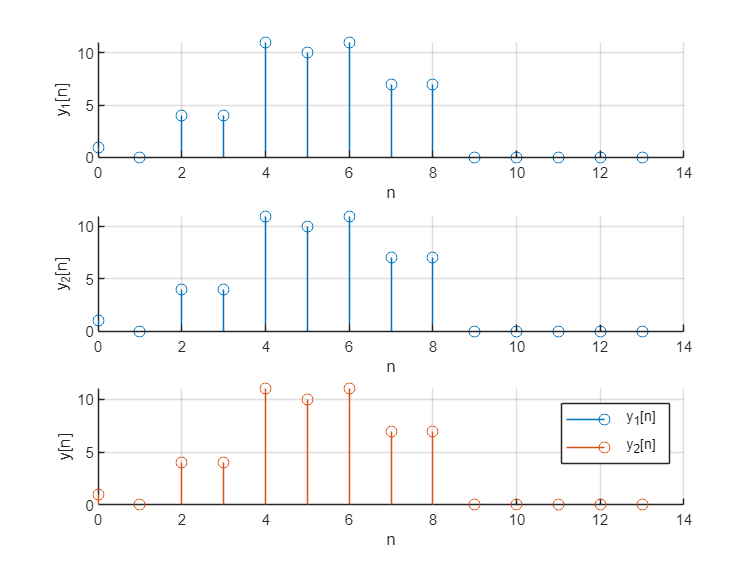

figure;
tiledlayout(3,1);
nexttile;
stem(ny,y1);
xlabel('n');ylabel('y_1[n]');grid on;box off;
nexttile;
stem(ny,y2);
xlabel('n');ylabel('y_2[n]');grid on;box off;
nexttile;
hold on;
stem(ny,y1);
stem(ny,y2);
grid on;
xlabel('n');
ylabel('y[n]');
legend('y_1[n]', 'y_2[n]');

isequal(y1,y2)

ans = logical
   1


They're overlaped in the figure and isequal. So $x[n]*h_1[n]+x[n]*h_2[n]=x[n]*(h_1[n]+h_2[n])$.

#### (d)

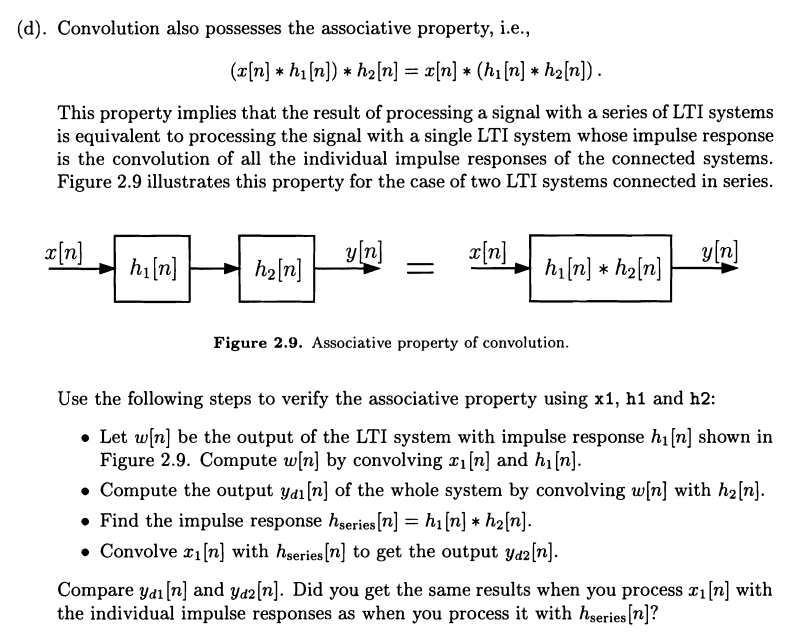

Initiate the three signals $x_1[n]$, $h_1[n]$, $h_2[n]$ and $nx1$, $nx2$.

x1 = [ones(1,5) zeros(1,5)];
h1 = [1 -1 3 0 4];
h2 = [0 0 1 0 3];
nx1 = 0:9;
nh1 = 0:4;

Calculate $w[n]$, $y_{d1}[n]$, $h_{series}[n]$, $y_{d2}[n]$.

w = conv(x1,h1);
nw = nx1(1)+nh1(1):nx1(end)+nh1(end);
yd1 = conv(w,h2);
nyd1 = nw(1)+nh1(1):nw(end)+nh1(end);
hseries = conv(h1,h2);
nhseries = nh1(1)+nh1(1):nh1(end)+nh1(end);
yd2 = conv(x1,hseries);
nyd2 = nx1(1)+nhseries(1):nx1(end)+nhseries(end);

Plot $y_{d1}$ and $y_{d2}$.

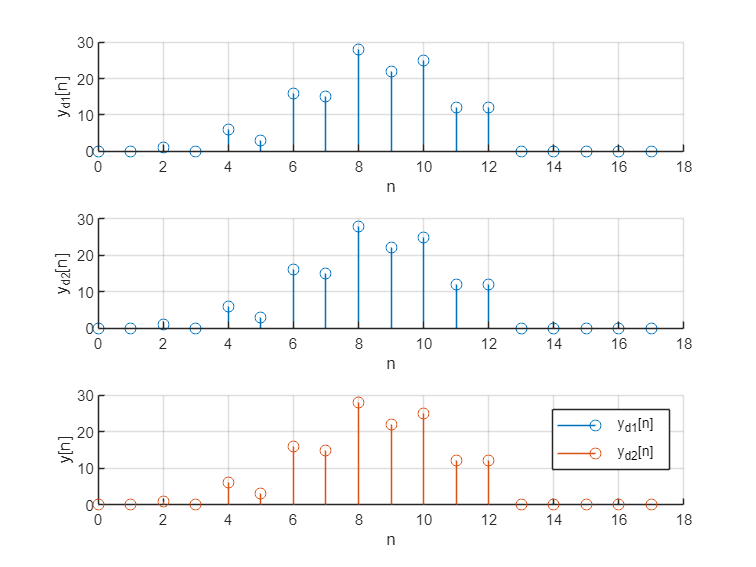

figure;
tiledlayout(3,1);
nexttile;
stem(nyd1,yd1);
xlabel('n');ylabel('y_{d1}[n]');grid on;box off;
nexttile;
stem(nyd2,yd2);
xlabel('n');ylabel('y_{d2}[n]');grid on;box off;
nexttile;
hold on;
stem(nyd1,yd1);
stem(nyd2,yd2);
grid on;
xlabel('n');
ylabel('y[n]');
legend('y_{d1}[n]', 'y_{d2}[n]');

isequal(yd1,yd2)

ans = logical
   1


They're overlaped in the figure and isequal. So $x[n]*(h_1[n]*h_2[n])=(x[n]*h_1[n])*h_2[n]$.

### 2.10

#### (a)

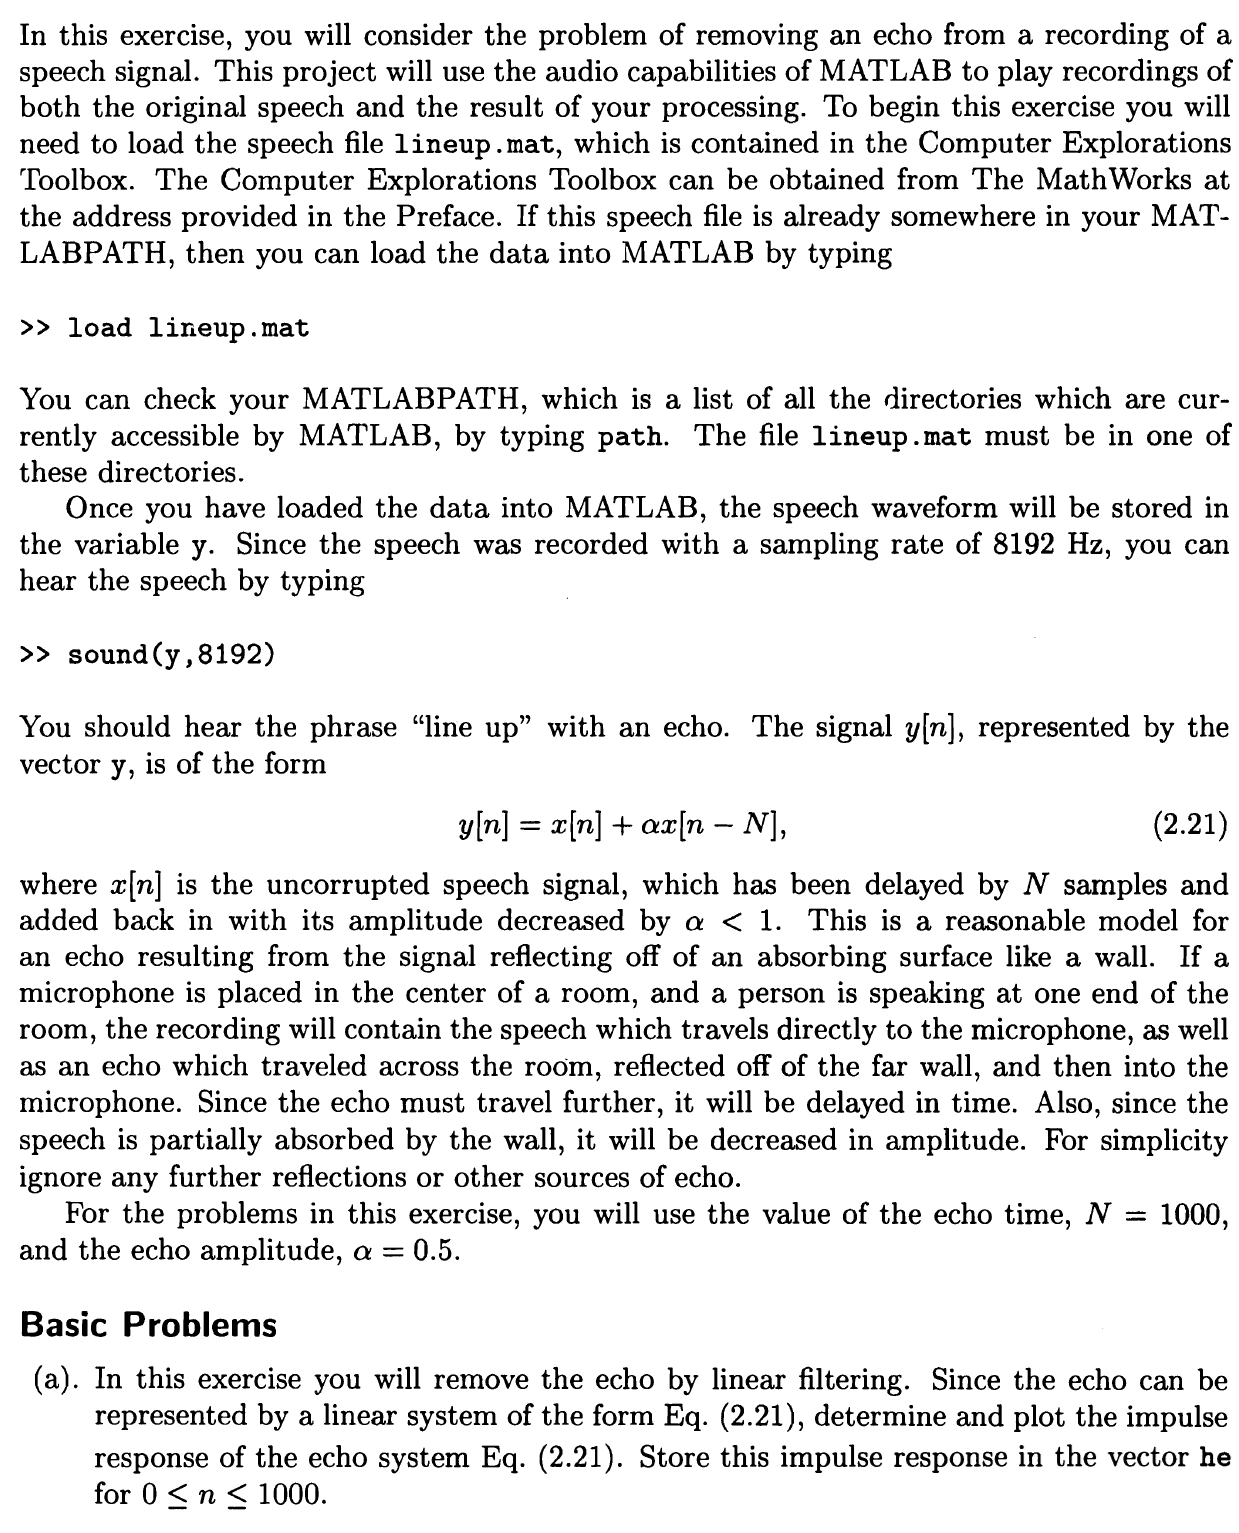

Initiate the environment.

clear;clc;
load lineup.mat
n = 0:1000;
alpha = 0.5;
N = 1000;

Use filter to get the vector $he$.

he = unitimpulse(n)+alpha*unitimpulse(n-N);

Plot $he$.

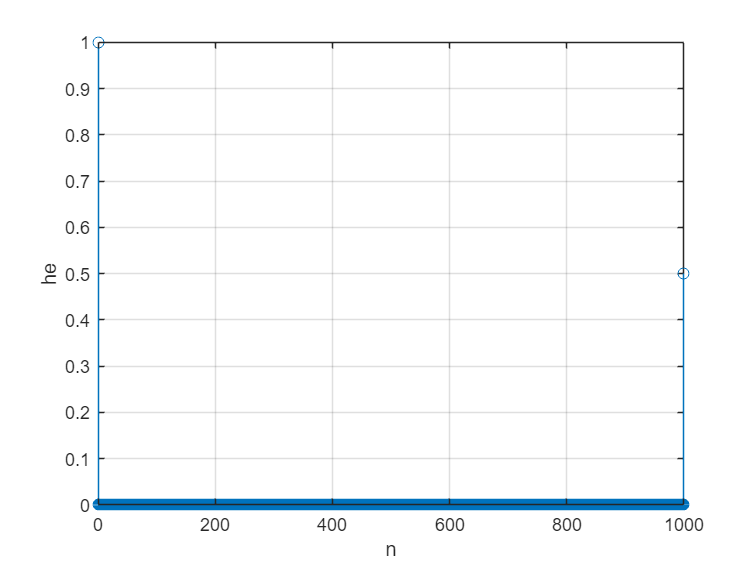

figure;
stem(n,he);
grid on;
xlabel('n');
ylabel('he');

#### (b)

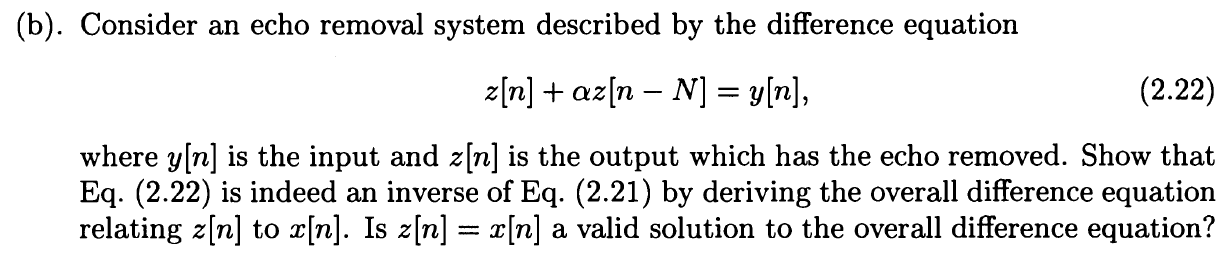

the overall difference equation: 


$$y[n]-(z[n]+\alpha z[n-N])=(x[n]+\alpha x[n-N])-y[n]$$



$$0=0$$


So that Eq.(2.22) is indeed an inverse of Eq.(2.21).

$z[n]=x[n]$ is a valid solution to the overall difference equation.

#### (c)

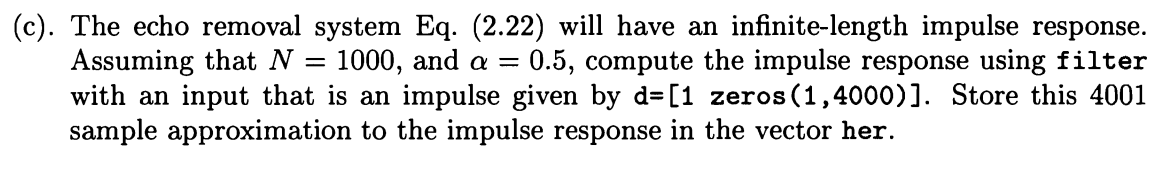

Initiate the impulse.

d = [1 zeros(1,4000)];

Use $filter()$ to get the vector $her$.

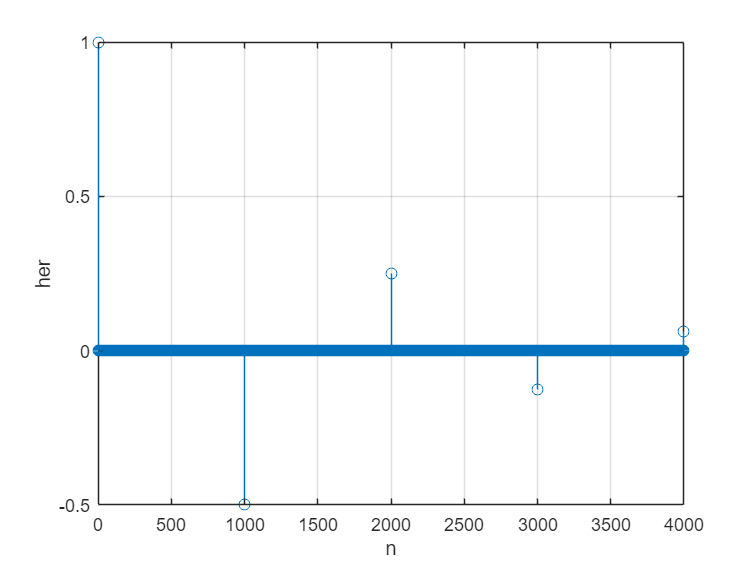

a = [1 zeros(1,999) 0.5];
her = filter(1,a,d);
n = 0:length(her)-1;
figure;
stem(n,her);
grid on;
xlabel('n');
ylabel('her');

#### (d)

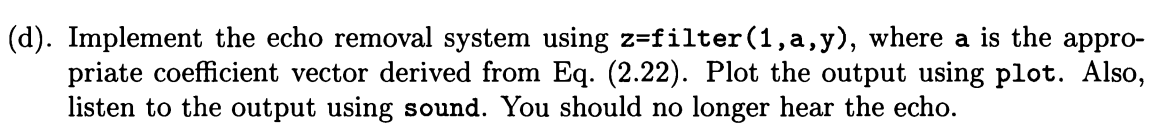

Load the speech file firstly.

load("lineup.mat")

Known from $Eq. (2.22)$, the $a$ should be [1 zeros(1, 999) 0.5] for $z[n] + 0.5*z[n-1000] = y[n]$.

So we can use remove the echo by using $filter()$ to get $z[n]$.

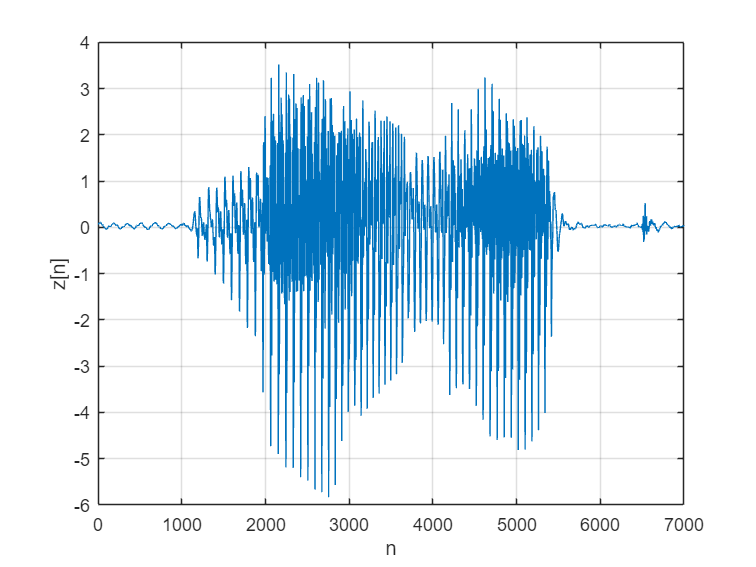

a = [1 zeros(1,999) 0.5];
z = filter(1,a,y);
nz =  1:length(z);
figure;
plot(nz,z);
xlabel('n');ylabel('z[n]');grid on;

Then use $sound()$ to listen the signal $z[n]$ with the frequency of 8192 Hz.

sound(z,8192);

We can hear that the echo is removed and we get a more clear sound.

#### (e)

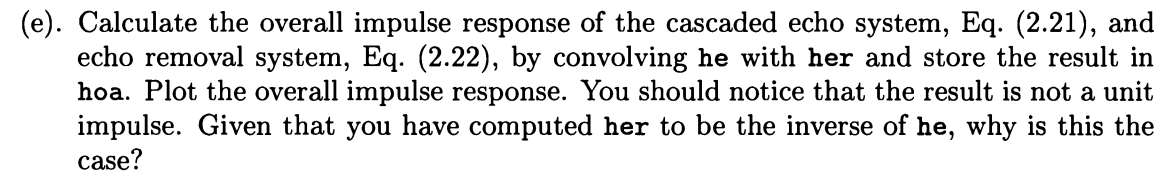

Calculate the result $hoa = he * her$.

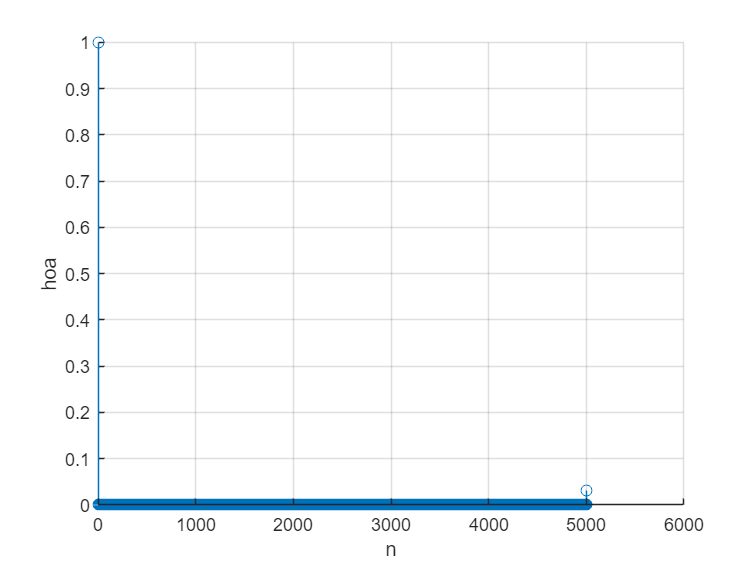

hoa = conv(he,her);
figure;
stem(hoa);grid on;box off;
ylabel('hoa');xlabel('n');

Since the $d$ is not an infinite-length unit impulse, the output $her[n]$ generated by $fliter(1, a, d)$ is not totally equal to $fliter(1, a, \sigma[n])$, which loses the values behind N>=4000.

So convolving $he$ and $her$ is not a unit impulse here.

#### (f)

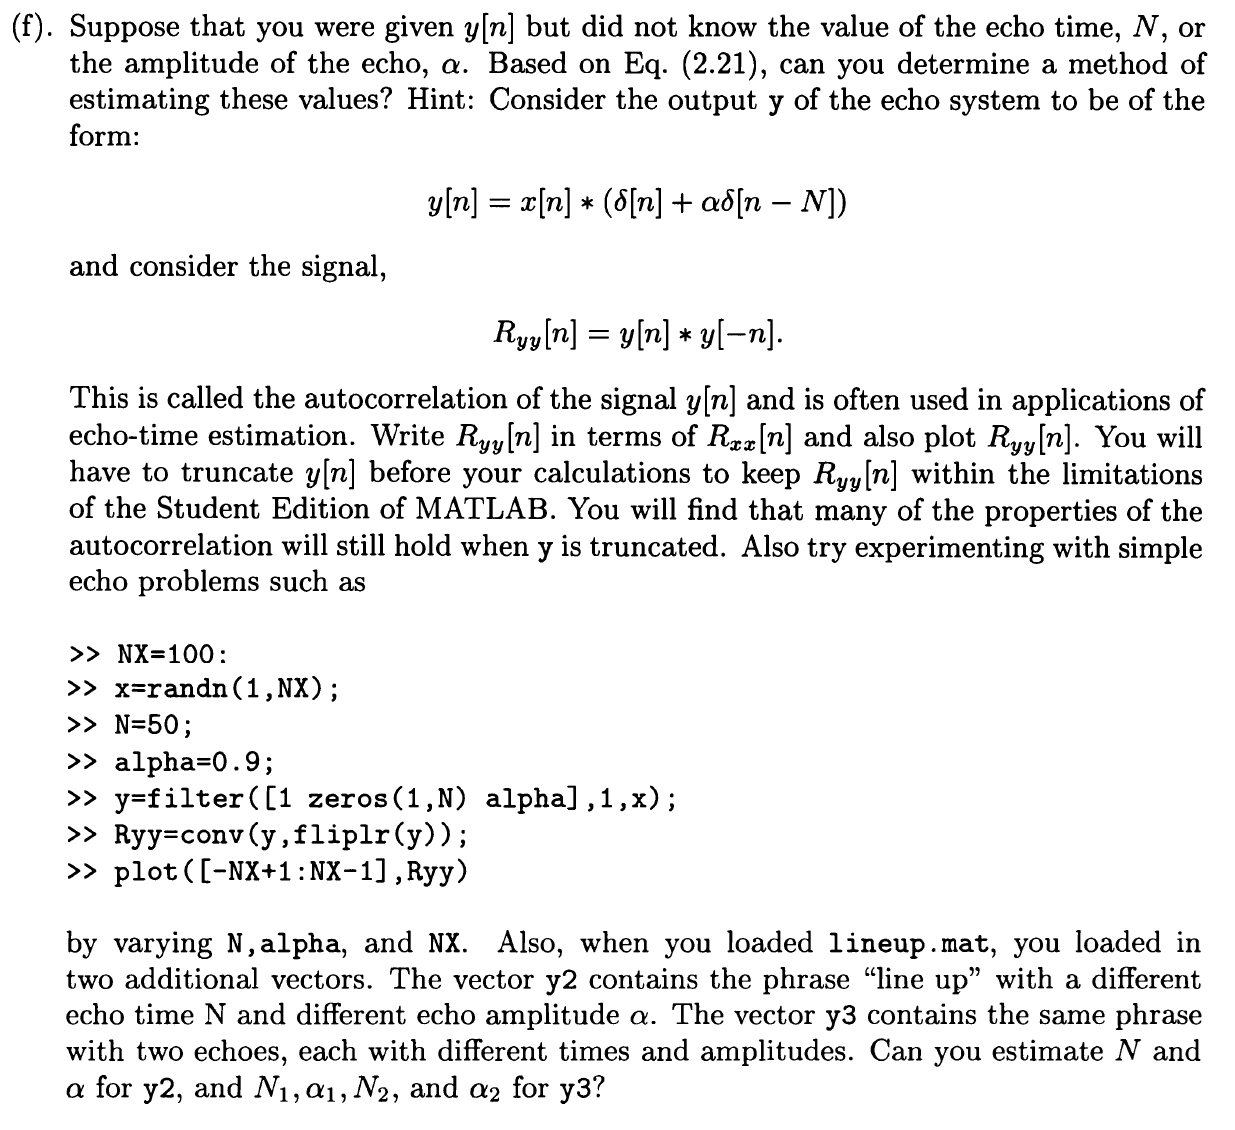


$$\begin{array}{rcl}
R_{yy}[n] & = & y[n]*y[-n] \\
  & = & x[n]*(\delta[n]+\alpha\delta[n-N])*x[-n]*(\delta[-n]+\alpha\delta[-n-N]) \\
  & = & R_{xx}[n]*((1+\alpha^2)\delta[n]+\alpha\delta[n-N]+\alpha\delta[-n-N]) \\
  & = & (1+\alpha^2)R_{xx}[n]+\alpha R_{xx}[n-N]+\alpha R_{xx}[n+N]
\end{array}$$


Calculate $R_{yy}[n]$.

ny = 1:length(y);
Ryy = conv(y,flip(y));
nRyy = ny(1)-ny(end):ny(end)-ny(1);

Plot $R_{yy}[n]$.

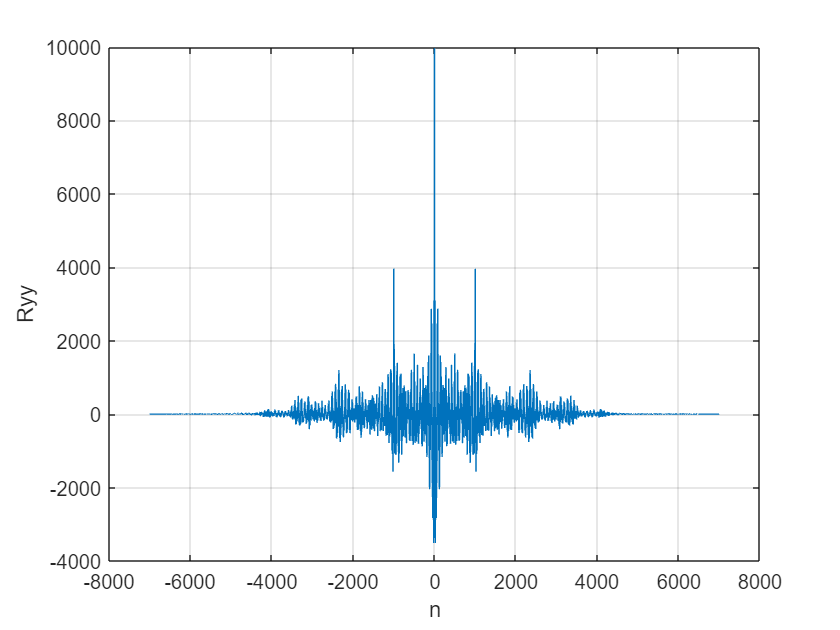

figure;
plot(nRyy,Ryy);
grid on;
xlabel('n');
ylabel('Ryy');

According to the property of Auto-Correlation signal, $R_{xx}[n]$ has the maximum when $n=0$ since $x[n]$ isn't a period signal, and the value when $|n|$ is large is so small compared to $R_{xx}[0]$ that it can be ignored.

Therefore, according to the equation $R_{yy}[n]= (1+\alpha^2)R_{xx}[n]+\alpha R_{xx}[n-N]+\alpha R_{xx}[n+N]$, the max local maximum within local maximum of $R_{yy}[n]$ is at $n=0$. But because when $n$ is close to 0, it also can be very big, so judging where the $R_{yy}[N]$ is need to take both it's value and it's $|n|$ into consideration. In this report, we simply use the first two values in the decreasing array of local maximums which is at $n\geq0$ as $R_{yy}[0]$ and $R_{yy}[n]$.

Since $R_{xx}[N]$, $R_{xx}[-N]$, $R_{xx}[2N]$, $R_{xx}[-2N]$ can be ignored compared to $R_{xx}[0]$, $\frac{R_{yy}[N]}{R_{yy}[0]}$ can be seen as the same as $\frac{\alpha}{1+\alpha^2}$. Solve and get $\alpha=\frac{R_{yy}[0]\pm\sqrt{R_{yy}[0]^2-4R_{yy}[N]^2}}{2R_{yy}[N]}$$

As above, calculate $N$ and $\alpha$ of $y[n]$.

% only care about n>=0
[local_maximum,local_maximum_idx] = all_local_maximum(Ryy((length(Ryy)+1)/2:end));
decresing_local_maximum_length = 1;
for i = 2:length(local_maximum)
    if local_maximum(i)>local_maximum(decresing_local_maximum_length)
        while local_maximum(i)>local_maximum(decresing_local_maximum_length)
            decresing_local_maximum_length = decresing_local_maximum_length-1;
        end
    end
    decresing_local_maximum_length = decresing_local_maximum_length+1;
    local_maximum(decresing_local_maximum_length) = local_maximum(i);
    local_maximum_idx(decresing_local_maximum_length) = local_maximum_idx(i);
end
N = abs(local_maximum_idx(2)-local_maximum_idx(1))

N = 1000

alpha = [(local_maximum(1)+sqrt(local_maximum(1)^2-4*local_maximum(2)^2))/(2*local_maximum(2));(local_maximum(1)-sqrt(local_maximum(1)^2-4*local_maximum(2)^2))/(2*local_maximum(2))]

alpha =     2.0249
    0.4938


Then try the experiment in the question.

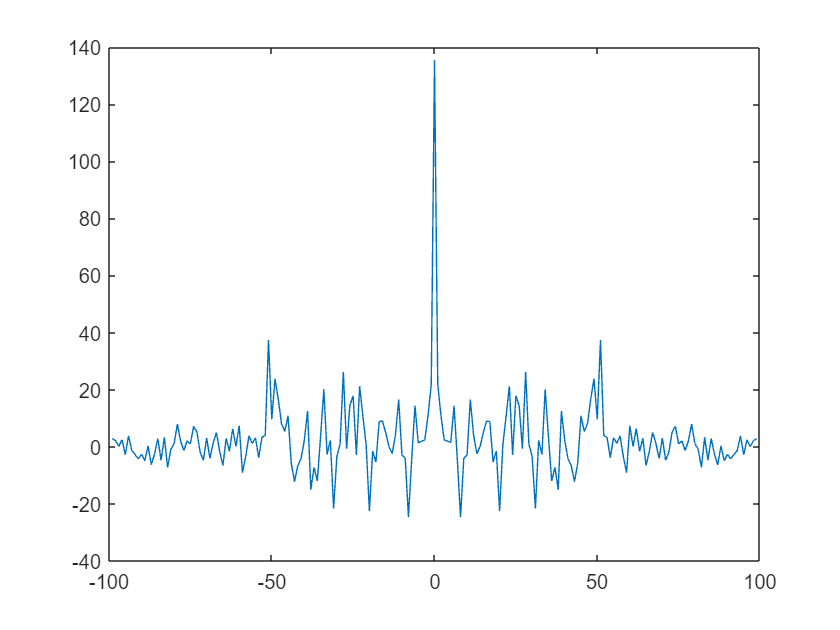

NX = 100;
x = randn(1,NX);
N = 50;
alpha = 0.9;
y = filter([1 zeros(1,N) alpha],1,x);
Ryy = conv(y,fliplr(y));
plot(-NX+1:NX-1,Ryy);

% only care about n>=0
[local_maximum,local_maximum_idx] = all_local_maximum(Ryy((length(Ryy)+1)/2:end));
decresing_local_maximum_length = 1;
for i = 2:length(local_maximum)
    if local_maximum(i)>local_maximum(decresing_local_maximum_length)
        while local_maximum(i)>local_maximum(decresing_local_maximum_length)
            decresing_local_maximum_length = decresing_local_maximum_length-1;
        end
    end
    decresing_local_maximum_length = decresing_local_maximum_length+1;
    local_maximum(decresing_local_maximum_length) = local_maximum(i);
    local_maximum_idx(decresing_local_maximum_length) = local_maximum_idx(i);
end
N = abs(local_maximum_idx(2)-local_maximum_idx(1))

N = 51

alpha = [(local_maximum(1)+sqrt(local_maximum(1)^2-4*local_maximum(2)^2))/(2*local_maximum(2));(local_maximum(1)-sqrt(local_maximum(1)^2-4*local_maximum(2)^2))/(2*local_maximum(2))]

alpha =     3.3182
    0.3014


In this case, since the y is generated by filter and is incomplete, so the $R_{yy}$ isn't the real $R_{yy}$, which leads to more inaccurate $\alpha$ and may leads to the second local maximum being not $R_{yy}[N]$ and the $N$ going wrong too.

Then deal with $y_2[n]$.

ny2 = 1:length(y2);
Ryy2 = conv(y2,flip(y2));
nRyy2 = ny2(1)-ny2(end):ny2(end)-ny2(1);

Plot $y_2[n]$.

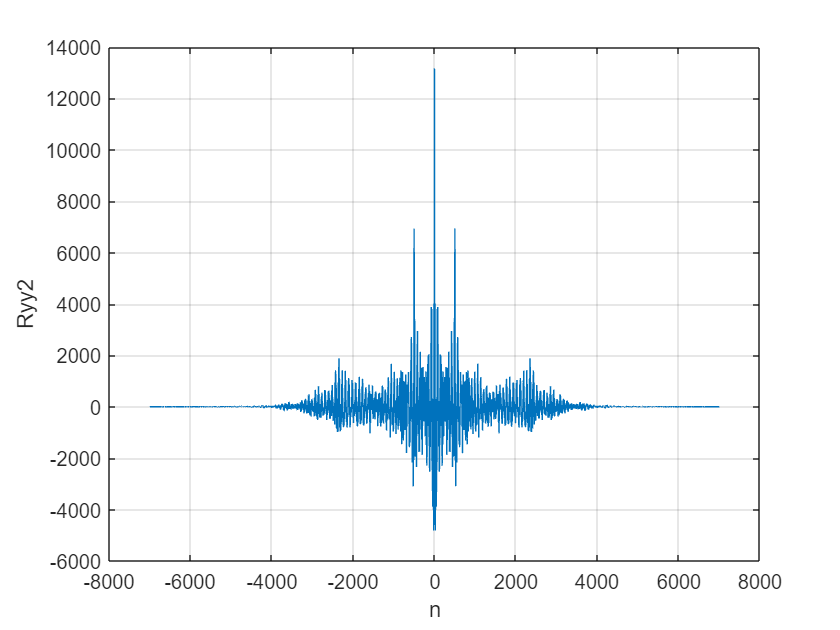

figure;
plot(nRyy2,Ryy2);
grid on;
xlabel('n');
ylabel('Ryy2');

Calculate $N$ and $\alpha$.

% only care about n>=0
[local_maximum,local_maximum_idx] = all_local_maximum(Ryy2((length(Ryy2)+1)/2:end));
decresing_local_maximum_length = 1;
for i = 2:length(local_maximum)
    if local_maximum(i)>local_maximum(decresing_local_maximum_length)
        while local_maximum(i)>local_maximum(decresing_local_maximum_length)
            decresing_local_maximum_length = decresing_local_maximum_length-1;
        end
    end
    decresing_local_maximum_length = decresing_local_maximum_length+1;
    local_maximum(decresing_local_maximum_length) = local_maximum(i);
    local_maximum_idx(decresing_local_maximum_length) = local_maximum_idx(i);
end
N = abs(local_maximum_idx(2)-local_maximum_idx(1))

N = 501

alpha = [(local_maximum(1)+sqrt(local_maximum(1)^2-4*local_maximum(2)^2))/(2*local_maximum(2));(local_maximum(1)-sqrt(local_maximum(1)^2-4*local_maximum(2)^2))/(2*local_maximum(2))]

alpha =    0.9487 + 0.3163i
   0.9487 - 0.3163i


Then deal with $y_3[n]$.


$$\begin{array}{rcl}
R_{yy}[n] & = & y[n]*y[-n] \\
  & = & x[n]*(\delta[n]+\alpha_1\delta[n-N_1]+\alpha_2\delta[n-N_2])*x[-n]*(\delta[-n]+\alpha_1\delta[-n-N_1]+\alpha_2\delta[-n-N_2]) \\
  & = & R_{xx}[n]*((1+\alpha_1^2+\alpha_2^2)\delta[n]+\alpha_1\delta[n-N_1]+\alpha_1\delta[-n-N_1]+\alpha_2\delta[n-N_2]+\alpha_2\delta[-n-N_2]+\alpha_1\alpha_2\delta[-n-N_2+N_1]+\alpha_1\alpha_2\delta[-n-N_1+N_2]) \\
  & = & (1+\alpha_1^2+\alpha_2^2)R_{xx}[n]+\alpha_1 R_{xx}[n-N_1]+\alpha_1 R_{xx}[n+N_1]+\alpha_2 R_{xx}[n-N_2]+\alpha_2 R_{xx}[n+N_2]+\alpha_1\alpha_2 R_{xx}[n+N_2-N_1]+\alpha_1\alpha_2 R_{xx}[n+N_1-N_2]
\end{array}$$


As mentioned above, if $N_2 \neq 2N_1$, we define the first three values in the decreasing array of local maximums which is at $n\geq0$ as "peak", The highest one is $R_{yy}[0]$. The fasthest is $R_{yy}[N_2]$. The rest is $R_{yy}[N_1]$. There is no $R_{yy}[N_2-N_1]$ because it's between $R_{yy}[N_1]$ and $R_{yy}[N_2]$ and it's smaller than both of them. But when we determined $R_{yy}[N_1]$ and $R_{yy}[N_2]$, we also get $N_1$ and $N_2$ so we can get the value of $R_{yy}[N_2-N_1]$.


$$\alpha_1=\frac{R_{yy}[N_2-N_1]}{R_{yy}[N_2]}$$
    
$$\alpha_2=\frac{R_{yy}[N_2-N_1]}{R_{yy}[N_1]}$$


If $N_2=2N_1$, the $R_{yy}[N_2-N_1]$ is overlaped by $R_{yy}[N_1]$ so we can't get the value of $R_{yy}[N_2-N_1]$ and the computation will be more complex.

$\frac{R_{yy}[N_2]}{R_{yy}[0]}=\frac{\alpha_2}{1+\alpha_1^2+\alpha_2^2}$, $\alpha_1=\sqrt{-\alpha_2^2+\frac{R_{yy}[0]}{R_{yy}[N_2]}\alpha_2-1}$


$$\frac{R_{yy}[N_1]}{R_{yy}[N_2]}=\frac{\alpha_1}{\alpha_2}=\frac{\sqrt{-\alpha_2^2+\frac{R_{yy}[0]}{R_{yy}[N_2]}\alpha_2-1}}{\alpha_2}$$


Solve and get $\alpha_2$ and substitute to get $\alpha_1$.

ny3 = 1:length(y3);
Ryy3 = conv(y3,flip(y3));
nRyy3 = ny3(1)-ny3(end):ny3(end)-ny3(1);

Plot $y_3[n]$.

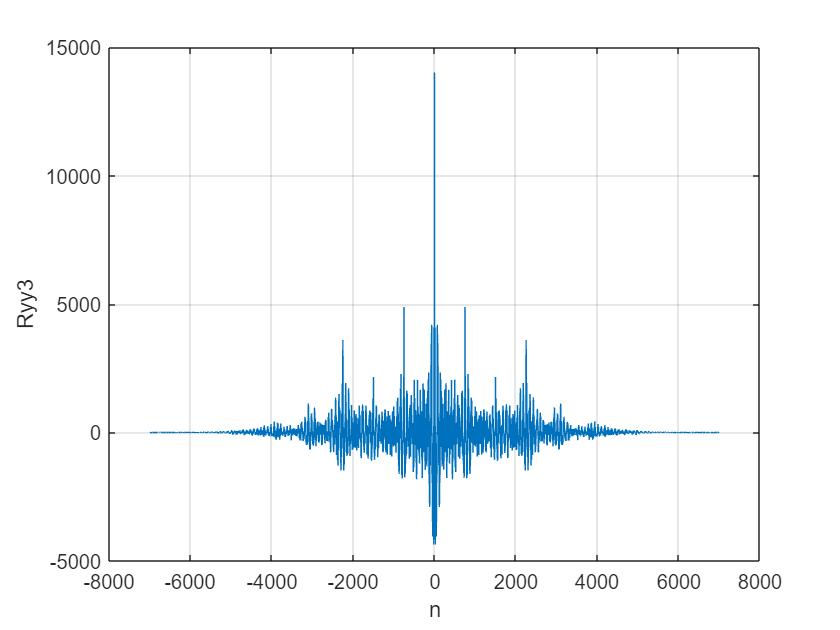

figure;
plot(nRyy3,Ryy3);
grid on;
xlabel('n');
ylabel('Ryy3');

Calculate $N$ and $\alpha$. To figure out how many peak there are, we decide to judge whether the 6th and 7th largest local maximum more closer to 5th one than 8th.

% only care about n>=0
[local_maximum,local_maximum_idx] = all_local_maximum(Ryy3((length(Ryy3)+1)/2:end));
decresing_local_maximum_length = 1;
for i = 2:length(local_maximum)
    if local_maximum(i)>local_maximum(decresing_local_maximum_length)
        while local_maximum(i)>local_maximum(decresing_local_maximum_length)
            decresing_local_maximum_length = decresing_local_maximum_length-1;
        end
    end
    decresing_local_maximum_length = decresing_local_maximum_length+1;
    local_maximum(decresing_local_maximum_length) = local_maximum(i);
    local_maximum_idx(decresing_local_maximum_length) = local_maximum_idx(i);
end
syms a;
alpha2 = double(solve(sqrt(-a^2+local_maximum(1)/local_maximum(3)*a-1)/a==local_maximum(2)/local_maximum(3),a));
N1 = local_maximum_idx(2)-local_maximum_idx(1)

N1 = 751

N2 = local_maximum_idx(3)-local_maximum_idx(1)

N2 = 2252

alpha1 = local_maximum(2)/local_maximum(3)*alpha2

alpha1 =     0.4648
    1.3947


alpha2

alpha2 =     0.3424
    1.0274


Since $\alpha_1$ and $\alpha_2$ smaller than 1.

alpha1 = alpha1(1)

alpha1 = 0.4648

alpha2 = alpha2(1)

alpha2 = 0.3424

### Functions

Unit impulse function

function y = unitimpulse (x)
    y = double(x==0);
end

Find next local maximum and it's index

function [max,idx] = next_local_maximum (array,idx)
    if idx >= length(array)
        idx = -1;
        max = -inf;
        return;
    end
    while idx ~= length(array) && array(idx+1) <= array(idx)
       idx = idx+1;
    end
    if idx== length(array)
        idx = -1;
        max = -inf;
        return;
    end
    while idx ~= length(array) && array(idx+1) >= array(idx)
       idx = idx+1;
    end
    max = array(idx);
end

Find all local maximum and its index

function [res,res_idx] = all_local_maximum (array)
    if array(1)>array(2)
        res = array(1);
        res_idx = 1;
        res_num = 1;
    else
        res = [];
        res_idx = [];
        res_num = 0;
    end
    [value,idx] = next_local_maximum(array,2);
    while idx ~= -1
        if res_num == length(res)
            res = [res zeros(1,100)];
            res_idx = [res_idx zeros(1,100)];
        end
        res_num = res_num+1;
        res(res_num) = value;
        res_idx(res_num) = idx;
        [value,idx] = next_local_maximum(array,idx+1);
    end
    res = res(1:res_num);
    res_idx = res_idx(1:res_num);
end

## Expeience

Through Matlab work, I have a preliminary understanding of Matlab simulation tools in the signal and system of the application of the discipline. I'm more famililar with the usage of the function  and  and to form echo system and echo removal system. I also learned the properties of Auto-Correlation signal and how to use it to figure out the echo from a signal containing both original signal, by which we can know the echo time to get the distance or even approximately remove the echo to get a more clear signal. What I learned in this chapter is very useful in our daily life. And I will continuously improve myself.

## Score

涂峻绫（100），欧阳安男（100）